clc; clear; close all;


data = readtable('heart.csv');
fprintf('Shape: %d lines, %d columns\n', height(data), width(data));

Shape: 918 lines, 12 columns


disp('Columns:');

Columns:


disp(data.Properties.VariableNames);

    {'Age'}    {'Sex'}    {'ChestPainType'}    {'RestingBP'}    {'Cholesterol'}    {'FastingBS'}    {'RestingECG'}    {'MaxHR'}    {'ExerciseAngina'}    {'Oldpeak'}    {'ST_Slope'}    {'HeartDisease'}




% Duplicate and missing data check:
[uniqueRows, ia, ic] = unique(data, 'rows', 'stable');
n_dup = height(data) - height(uniqueRows);
fprintf('Righe duplicate trovate: %d (%.2f%%)\n\n', n_dup, n_dup/height(data)*100);

Righe duplicate trovate: 0 (0.00%)



missingCounts = sum(ismissing(data));
disp('Valori mancanti per colonna:');

Valori mancanti per colonna:


disp(missingCounts);

     0     0     0     0     0     0     0     0     0     0     0     0



% Train and test data division:

targetName = 'HeartDisease';

cv = cvpartition(data.(targetName), 'HoldOut', 0.2); %stabilisco così lo split 80/20

dataTrain = data(training(cv),:);
dataTest = data(test(cv), :);

y_train = dataTrain.(targetName);
y_test = dataTest.(targetName);

% Subtract target column from features:

dataTrain.(targetName) = [];
dataTest.(targetName) = [];

% Data pre-processing:

% Data normalization with z-score method:
numVars = varfun(@isnumeric, dataTrain, 'OutputFormat','uniform');
numTrain = dataTrain(:, numVars);
catTrain = dataTrain(:, ~numVars);

mu = varfun(@mean, numTrain);
sigma = varfun(@std, numTrain);
numTrainNorm = array2table((numTrain{:,:} - mu{:,:}) ./ sigma{:,:}, ...
    'VariableNames', numTrain.Properties.VariableNames);
numTest = dataTest(:, numVars);
numTestNorm = array2table((numTest{:,:} - mu{:,:}) ./ sigma{:,:}, ...
    'VariableNames', numTest.Properties.VariableNames);

% Categorical data conversion (from text to binary):

if ~isempty(catTrain)
    
    catEncodedTrain = [];
    catEncodedTest = [];
    catNames = catTrain.Properties.VariableNames;

    for i = 1:numel(catNames)

        colTrain = categorical(catTrain.(catNames{i}));
        colTest = categorical(dataTest.(catNames{i}), categories(colTrain));

        encodedTrain = dummyvar(colTrain);
        encodedTest = dummyvar(colTest);

        newNames = strcat(catNames{i}, "_", categories(colTrain));
        catEncodedTrain = [catEncodedTrain array2table(encodedTrain, "VariableNames", newNames')];
        catEncodedTest = [catEncodedTest array2table(encodedTest, "VariableNames",newNames')];

    end

    X_train = [numTrainNorm catEncodedTrain];
    X_test = [numTestNorm catEncodedTest];

else

    X_train = numTrainNorm;
    X_test = numTestNorm;

end

% Random Forest definition:
RFmodel = fitcensemble(X_train, y_train, ...
    'Method', 'Bag','NumLearningCycles', 100, ...
    'Learners', 'tree', 'ClassNames', unique(y_train));

% TEST SET VALIDATION (how does it perform with my test data?):
[y_pred, scores] = predict(RFmodel, X_test);

%is it accurate enough?
accuracy = mean(y_pred == y_test);

assert(numel(y_test)==size(scores,1));

[Xroc, Yroc, ~, AUC] = perfcurve(y_test, scores(:,2), 1);


fprintf('####### Model performance on test set #######\n');

####### Model performance on test set #######


fprintf('Accuracy: %.3f\n', accuracy);

Accuracy: 0.880


fprintf('AUC: %.3f\n\n', AUC);

AUC: 0.933



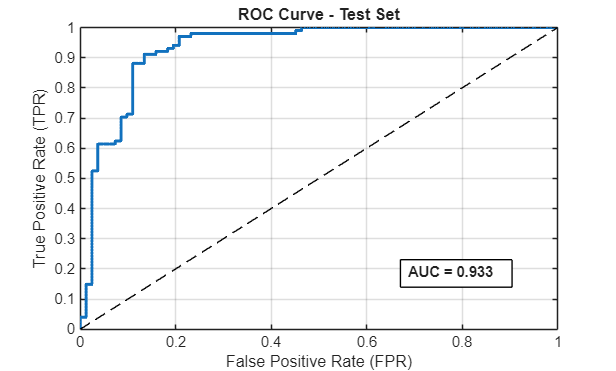

% ROC TEST SET CURVE
figure;
plot(Xroc,Yroc,'LineWidth',2);
hold on;
plot([0 1], [0 1], '--k')
xlabel('False Positive Rate (FPR)');
ylabel('True Positive Rate (TPR)');
title(sprintf('ROC Curve - Test Set',AUC));
grid on;
% --- Automatic placement of the AUC box ---

% Compute mean Y value (to estimate where the curve lies)
meanY = mean(Yroc);

if meanY < 0.5
    % ROC curve lies mainly in the lower half of the plot
    % -> Place AUC box in the top-left
    boxX = 0.1;
    boxY = 0.7;
else
    % ROC curve lies mainly in the upper half
    % -> Place AUC box in the bottom-right
    boxX = 0.65;
    boxY = 0.2;
end

% Create the AUC text box
aucText = sprintf('AUC = %.3f', AUC);
annotation('textbox', [boxX boxY 0.2 0.1], ...
           'String', aucText, ...
           'FitBoxToText', 'on', ...
           'BackgroundColor', 'white', ...
           'EdgeColor', 'black', ...
           'FontSize', 10, ...
           'FontWeight', 'bold');

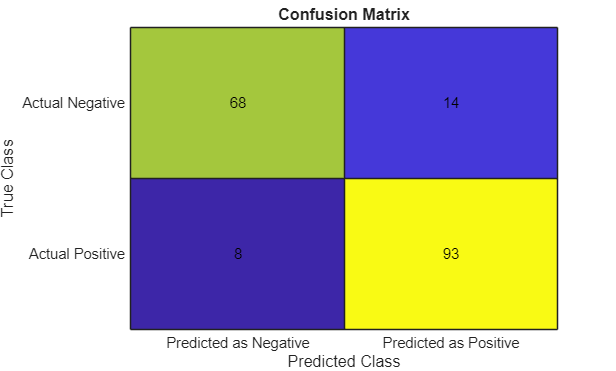

% Confusion matrix et al.

C = confusionmat(y_test, y_pred);
figure;
h = heatmap({'Predicted as Negative','Predicted as Positive'}, ...
             {'Actual Negative','Actual Positive'}, ...
             C, ...
             'CellLabelColor','black', ...
             'Colormap',parula, ...
             'ColorbarVisible','off');
title('Confusion Matrix');
xlabel('Predicted Class');
ylabel('True Class');

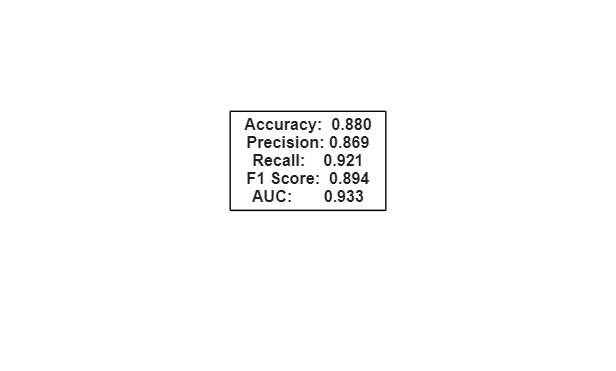

TP = C(2,2);
TN = C(1,1);
FP = C(1,2);
FN = C(2,1);

accuracy = (TP + TN)/sum(C(:));
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

figure ('Color', 'w');
axis off; 
metricsText = {
    sprintf('Accuracy:  %.3f', accuracy)
    sprintf('Precision: %.3f', precision)
    sprintf('Recall:    %.3f', recall)
    sprintf('F1 Score:  %.3f', f1_score)
    sprintf('AUC:       %.3f', AUC)
    };

annotation('textbox',[0.3 0.3 0.4 0.4], ...
    'String', strjoin(metricsText, newline), ...
    'FitBoxToText','on', ...
    'FontSize',11, ...
    'FontWeight','bold', ...
    'HorizontalAlignment','center', ...
    'BackgroundColor','white', ...
    'EdgeColor','black');

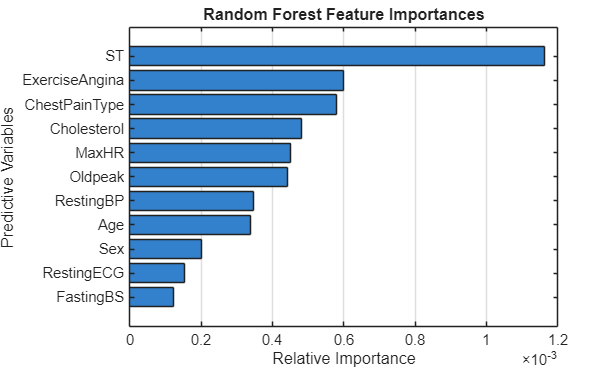

% Feature importance (how much does the single feature impact on the
% accuracy of my model?):
imp = predictorImportance(RFmodel);
varNames = RFmodel.PredictorNames;

% === Group features that came from the same categorical variable ===
groupedImportance = containers.Map;

for i = 1:numel(varNames)
    name = varNames{i};
    
    % Extract base variable name before the underscore (if any)
    underscoreIdx = strfind(name, '_');
    if ~isempty(underscoreIdx)
        baseName = name(1:underscoreIdx(1)-1);
    else
        baseName = name;
    end
    
    % Accumulate importance
    if isKey(groupedImportance, baseName)
        groupedImportance(baseName) = groupedImportance(baseName) + imp(i);
    else
        groupedImportance(baseName) = imp(i);
    end
end

% === Convert Map to arrays for plotting ===
groupNames = keys(groupedImportance);
groupValues = cell2mat(values(groupedImportance));

% === Sort by importance (descending) ===
[groupValues, sortIdx] = sort(groupValues, 'descend');
groupNames = groupNames(sortIdx);

% === Horizontal Bar Plot ===
figure('Color', 'w');
barh(groupValues, 'FaceColor', [0.2 0.5 0.8]);
title('Random Forest Feature Importances', 'FontWeight', 'bold');
xlabel('Relative Importance');
ylabel('Predictive Variables');
grid on;

% === Beautify Axes ===
ax = gca;
ax.YTick = 1:numel(groupNames);
ax.YTickLabel = groupNames;
ax.FontSize = 10;
ax.YDir = 'reverse';  % most important at top

set(gca, "XGrid", "on", "YGrid", "off")

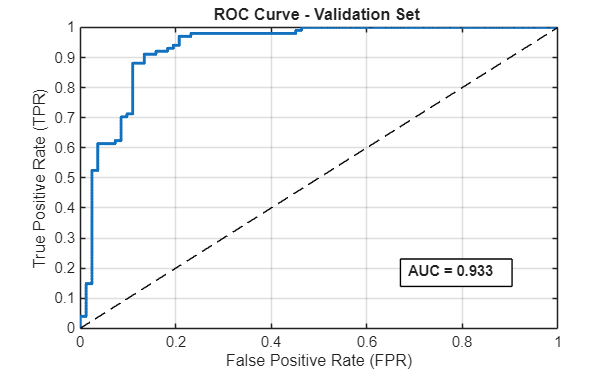





% ROC CURVE 
figure;
[Xroc, Yroc, ~, AUC_final] = perfcurve(y_test, scores(:,2), 1);
plot(Xroc, Yroc, 'LineWidth', 2);
hold on;
plot([0 1], [0 1], '--k');
xlabel('False Positive Rate (FPR)');
ylabel('True Positive Rate (TPR)');
title(sprintf('ROC Curve - Validation Set ', AUC_final));
grid on;
% --- Automatic placement of the AUC box ---

% Compute mean Y value (to estimate where the curve lies)
meanY = mean(Yroc);

if meanY < 0.5
    % ROC curve lies mainly in the lower half of the plot
    % -> Place AUC box in the top-left
    boxX = 0.1;
    boxY = 0.7;
else
    % ROC curve lies mainly in the upper half
    % -> Place AUC box in the bottom-right
    boxX = 0.65;
    boxY = 0.2;
end

% Create the AUC text box
aucText = sprintf('AUC = %.3f', AUC_final);
annotation('textbox', [boxX boxY 0.2 0.1], ...
           'String', aucText, ...
           'FitBoxToText', 'on', ...
           'BackgroundColor', 'white', ...
           'EdgeColor', 'black', ...
           'FontSize', 10, ...
           'FontWeight', 'bold');